# Exercise 7

## 1.Noise generation and restoration

lena = imread('lena.jpg');
%a
lena_gauss = imnoise(lena,'gaussian');
%b
lena_salt = imnoise(lena,'salt & pepper');
%c
b=1500;
%rand(512,512)
[height,width] = size(lena);
noise = sqrt(-b * log((1-rand(height,width))));
lena_rayle = uint8(double(lena)+noise);

## 2.Restoration of Noisy Image

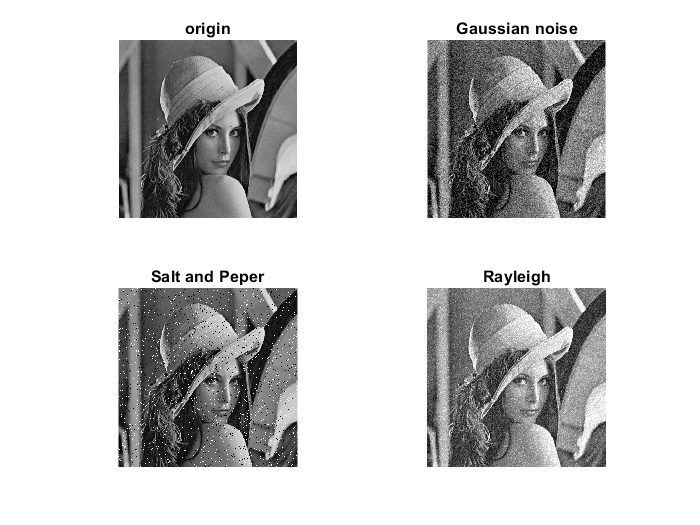

figure,
subplot(2,2,1);
imshow(lena),title('origin');
subplot(2,2,2);
imshow(lena_gauss),title('Gaussian noise')
subplot(2,2,3);
imshow(lena_salt),title('Salt and Peper')
subplot(2,2,4);
imshow(lena_rayle),title('Rayleigh')

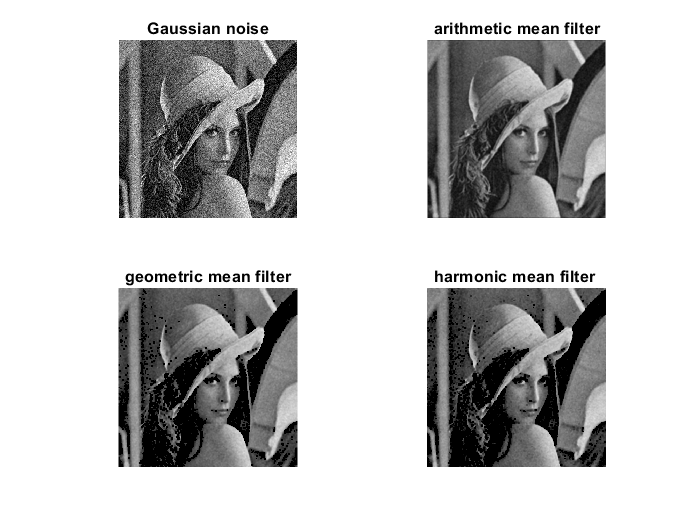

figure,
g = double(lena_gauss);
m = 5; n =5;
subplot(2,2,1);
imshow(lena_gauss);title('Gaussian noise')
f_arith = imfilter(g,fspecial('average',[m n]));
subplot(2,2,2);
imshow(uint8(f_arith)),title('arithmetic mean filter')
f_geome = exp(imfilter(log(g),ones(m,n),'replicate')).^(1/(m*n));
subplot(2,2,3);
imshow(uint8(f_geome)),title('geometric mean filter')
f_harmo = (m*n) ./ imfilter(1 ./ (g + eps), ones(m, n), 'replicate');
subplot(2,2,4);
imshow(uint8(f_harmo)),title('harmonic mean filter ')

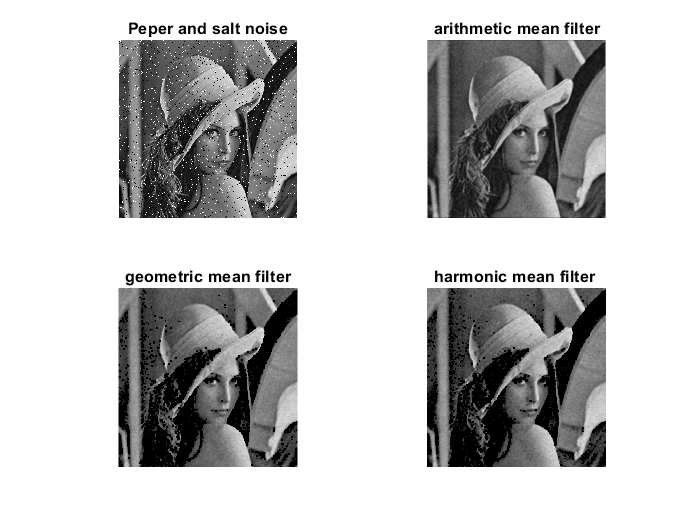

figure,
g = double(lena_gauss);
m = 5; n =5;
subplot(2,2,1);
imshow(lena_salt);title('Peper and salt noise')
f_arith = imfilter(g,fspecial('average',[m n]));
subplot(2,2,2);
imshow(uint8(f_arith)),title('arithmetic mean filter')
f_geome = exp(imfilter(log(double(g)),ones(m,n),'replicate')).^(1/(m*n));
subplot(2,2,3);
imshow(uint8(f_geome)),title('geometric mean filter')
f_harmo = (m*n) ./ imfilter(1 ./ (double(g) + eps), ones(m, n), 'replicate');
subplot(2,2,4);
imshow(uint8(f_harmo)),title('harmonic mean filter ')

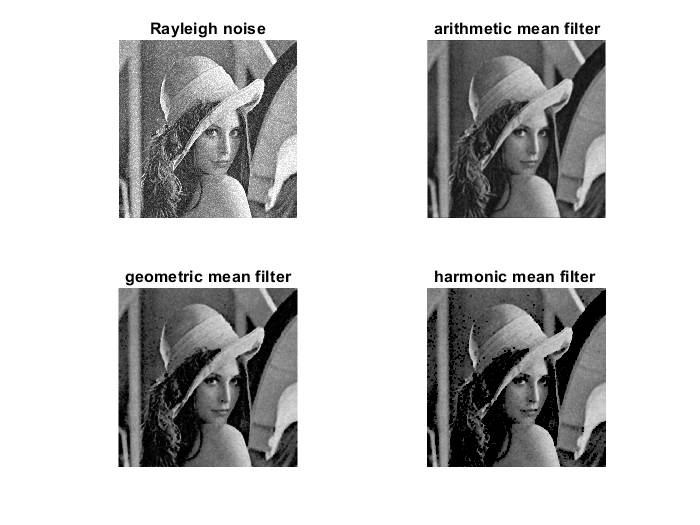

figure,
g = double(lena_gauss);
m = 5; n =5;
subplot(2,2,1);
imshow(lena_rayle);title('Rayleigh noise')
f_arith = imfilter(g,fspecial('average',[m n]));
subplot(2,2,2);
imshow(uint8(f_arith)),title('arithmetic mean filter')
f_geome = exp(imfilter(log(g+0.0001),ones(m,n),'replicate')).^(1/(m*n));
subplot(2,2,3);
imshow(uint8(f_geome)),title('geometric mean filter')
f_harmo = (m*n) ./ imfilter(1 ./ (g + 0.0001), ones(m, n), 'replicate');
subplot(2,2,4);
imshow(uint8(f_harmo)),title('harmonic mean filter ')

## 3.Noised cleaning with Weighted Median Filter

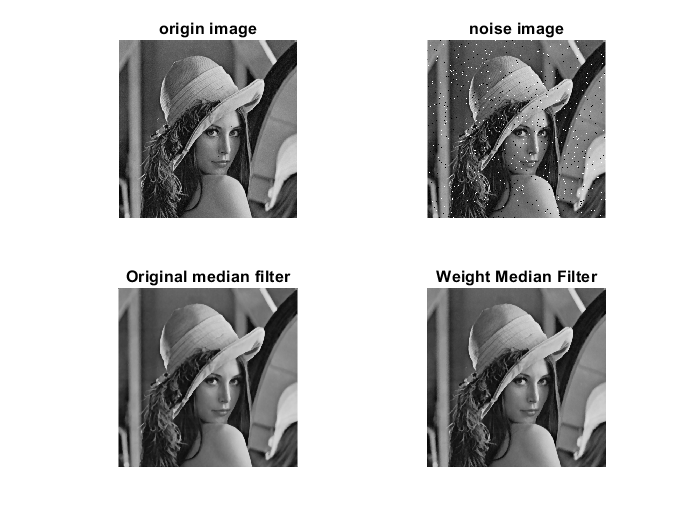

im = imread('lena.jpg');
%doc imnoise
%im = double(im);
a = imnoise(im,'salt & pepper',0.02);
%a = double(z);
%b = zeros(size(a));
W = ones(5);
W(3,3) = 5;
% W = W/29;
% b = double(a);
% [row, col] = size(a);

% for x = 3:1:row-2
%     for y = 3:1:col-2
%         a1 = [W(1)*a(x-2,y-2) W(2)*a(x-2,y-1) W(3)*a(x-2,y) W(4)*a(x-2,y+1) W(5)*a(x-2,y+2) ...
%         W(6)*a(x-1,y-2) W(7)*a(x-1,y-1) W(8)*a(x-1,y) W(9)*a(x-1,y+1) W(10)*a(x-1,y+2) ...
%         W(11)*a(x,y-2) W(12)*a(x,y-1) W(13)*a(x,y) W(14)*a(x,y+1) W(15)*a(x,y+2) ...
%         W(16)*a(x+1,y-2) W(17)*a(x+1,y-1) W(18)*a(x+1,y) W(19)*a(x+1,y+1) W(20)*a(x+1,y+2) ...
%         W(21)*a(x+2,y-2) W(22)*a(x+2,y-1) W(23)*a(x+2,y) W(24)*a(x+2,y+1) W(25)*a(x+2,y+2)];      
%         a2 = sort(a1);
%         med = a1(13);
%         b(x,y) = med;
%     end
% end

figure,
subplot(2,2,1);
imshow(uint8(im)); title('origin image')
% imshow(uint8(b))
% uint8(b)
subplot(2,2,2);
imshow(uint8(a)); title('noise image')
subplot(2,2,3);
out_put1 = med_filter(a,5);
imshow(uint8(out_put1));title('Original median filter')
subplot(2,2,4);
out_put = weightedmedianfilter(a,5,W);
imshow(out_put);title('Weight Median Filter')

%out_put1

out_put1 = 512×512 uint8 matrix
     0     0   136   129   129   129   129   129   134   134   131   131   131   129   129   129   129   129   128   128   128   128   128   129   129   126   126   126   126   126   127   127   127   127   127   127   127   133   133   135   136   142   142   142   143   148   148   149   143   143
     0   136   137   136   136   134   134   134   136   134   134   134   134   131   131   132   132   132   132   132   129   129   129   131   130   130   130   129   129   129   129   129   128   128   128   133   133   135   135   142   142   142   143   143   148   149   149   149   149   149
   137   137   137   137   137   136   138   136   136   135   135   135   135   134   134   134   134   134   134   132   132   132   131   132   131   131   130   130   129   129   129   129   128   131   133   134   134   135   142   142   142   143   143   148   150   150   149   149   149   149
   136   136   137   136   136   135   136   136   136   134   13